load store\POI30DS1.mat

n = 2000;
n = 11625; %brydes??
n = 4664;
x = POI.loadPOI(poi(n));
k1 = POI.k1;
k2 = POI.k2;

[S,f] = POI.PowerSpectrum(x);
Smf = medfilt1(S, POI.FreqMF, [], 1, "omitnan","truncate");
Snoise = median(Smf, 2);
Snoisesmooth = smoothdata(Snoise, "gaussian", POI.SMedSmooth);
lims = log([prctile(S, 0.001, "all"), max(S, [], "all")]);
Sw = S./Snoise;

t = (0:size(S, 2)-1)*(POI.Nfft - POI.Noverlap)/POI.fs;

figure
subplot(2, 1, 1)
Tools.plotTF(S, f, false, true, t);
clim(lims)
subplot(2, 1, 2)
Tools.plotTF(Smf, f, false, true, t);
clim(lims)
figure
hold on
plot(f, Snoisesmooth)
plot(f, Snoise)
yticks([])
[probsnw, mu_snw, mu_nsnw, sigma_snw, sigma_nsnw, pi_snw, pi_nsnw, n_iternw, convergednw, ~] = SignalDetection.softSignalDetectionGMM(S(k1:k2, :), POI.M);
[probsw, mu_sw, mu_nsw, sigma_sw, sigma_nsw, pi_sw, pi_nsw, n_iterw, convergedw, ~] = SignalDetection.softSignalDetectionGMM(Sw(k1:k2, :), POI.M);
figure
ax1 = subplot(311);
Tools.plotTF(S, f, false, true, t);
xlim([0, t(end)])
clim(lims)
ax2 = subplot(312);
hold on
plot(t, H)
plot(t, Hw)
hold off
xlim([0, t(end)])
ax3 = subplot(313);
hold on
plot(t, probs)
plot(t, probsw)
hold off
xlim([0, t(end)])
linkaxes([ax1, ax2, ax3], 'x')
lims = [min([H;Hw], [], "all"), max([H;Hw], [], "all")];
bins = linspace(lims(1), lims(2), 80);
xp = linspace(lims(1), lims(2), 1000);
figure
subplot(221)
hold on
histogram(H, bins, "Normalization","pdf");
plot(xp, gmm.ComponentProportion(1)*normpdf(xp, gmm.mu(1), sqrt(gmm.Sigma(:,:,1))), "k");
plot(xp, gmm.ComponentProportion(2)*normpdf(xp, gmm.mu(2), sqrt(gmm.Sigma(:,:,2))), "k");
hold off
subplot(222)
hold on
histogram(H, bins, "Normalization","cdf");
plot(xp, cdf(gmm, xp'));
hold off
subplot(223)
hold on
histogram(Hw, bins, "Normalization","pdf");
plot(xp, gmmw.ComponentProportion(1)*normpdf(xp, gmmw.mu(1), sqrt(gmmw.Sigma(:,:,1))), "k");
plot(xp, gmmw.ComponentProportion(2)*normpdf(xp, gmmw.mu(2), sqrt(gmmw.Sigma(:,:,2))), "k");
hold off
subplot(224)
hold on

plot(xp, cdf(gmmw, xp'));
hold off

info = POI.DatasetInfo()
ds1size = sum([info.Dataset] == 1)
ds2size = sum([info.Dataset] == 2)
ds1 = info([info.Dataset] == 1);
ds2 = info([info.Dataset] == 2);
path = convertCharsToStrings(ds1(1).folder) + "\"+ convertCharsToStrings(ds1(1).name)
xtest = audioread(path);
log2(numel(xtest))
numel(xtest)/POI.fs/60
numel(xtest)/POI.fs*ds1size/60/60
(2^11)/POI.fs

idx = 10:5:1536;
poi_nw = POI.FindPOI('gmm', 2, idx, false);
poi_w = POI.FindPOI('gmm', 2, idx, true);
save store\POINW125 poi_nw
save store\POIW125 poi_w

load store\POINW125.mat
load store\POIW125.mat


yl = "Proportion";
histw = 400;
histh = 300;
scatw = 270;
scath = 200;

fig = figure;
hold on
b = 0:10:200;
histogram([poi_nw.Iterations], b, "Normalization","probability")
histogram([poi_w.Iterations], b, "Normalization","probability")
hold off
xlabel('Iterations')
cc = sum([poi_w.Converged] & [poi_nw.Converged]);
nn = sum(~[poi_w.Converged] & ~[poi_nw.Converged]);
cn = sum([poi_w.Converged] & ~[poi_nw.Converged]);
nc = sum(~[poi_w.Converged] & [poi_nw.Converged]);
totw = sum([poi_w.Converged]);
totnw =sum([poi_nw.Converged]);
poi_nw_c = poi_nw([poi_nw.Converged]);
poi_w_c = poi_w([poi_w.Converged]);

ylabel(yl)
Tools.saveFig(fig, histw, histh, "hist_iter")

fig = figure;
hold on
histogram([poi_nw_c.LogLikelihood], "Normalization","probability")
histogram([poi_w_c.LogLikelihood], "Normalization","probability")
hold off
xlabel('Log-likelihood')
ylabel(yl)
Tools.saveFig(fig, histw, histh, "hist_ll")

b = (0:0.08:2.5);
fig = figure;
hold on
histogram([poi_nw_c.MeanDelta], b, "Normalization","probability")
histogram([poi_w_c.MeanDelta], b,  "Normalization","probability")
hold off
xlabel('\delta')
ylabel(yl)
xlim([0, 2.1])
Tools.saveFig(fig, histw, histh, "hist_delta")

fig = figure;
hold on
b = (0:0.04:0.9);
histogram([poi_nw_c.SignalProportion],b,  "Normalization","probability")
histogram([poi_w_c.SignalProportion],b, "Normalization","probability")
hold off
xlabel('p(C_s)')
ylabel(yl)
Tools.saveFig(fig, histw, histh, "hist_pcs")

b = (0:0.01:0.2)*100;
fig = figure;
hold on
histogram([poi_nw_c.ClassContamination]*100, b, "Normalization","probability")
histogram([poi_w_c.ClassContamination]*100, b, "Normalization","probability")
hold off
xlabel('\chi (%)')
ylabel(yl)
Tools.saveFig(fig, histw, histh, "hist_contam")


fig = figure;
Tools.scatter2groups([poi_nw_c.SignalStd], [poi_nw_c.NoSignalStd], [poi_w_c.SignalStd], [poi_w_c.NoSignalStd])
ylabel("\sigma_n")
xlabel("\sigma_s")
xlim([0 1.2])
ylim([0 0.3])
Tools.saveFig(fig, scatw, scath, "scatter_std")

fig = figure;
Tools.scatter2groups([poi_nw_c.SignalMean], [poi_nw_c.NoSignalMean], [poi_w_c.SignalMean], [poi_w_c.NoSignalMean])
ylabel("\mu_n")
xlabel("\mu_s")
xlim([2, 5.25])
ylim([4.2, 5.2])
Tools.saveFig(fig, scatw, scath, "scatter_mu")

fig = figure;
Tools.scatter2groups([poi_nw_c.MeanDelta], [poi_nw_c.ClassContamination]*100, [poi_w_c.MeanDelta], [poi_w_c.ClassContamination]*100)
xlabel('\delta')
ylabel('\chi (%)')
ylim([0, 20]);
xlim([0,2])
Tools.saveFig(fig, scatw, scath, "scat_delta_contam")


fig = figure;
Tools.scatter2groups([poi_nw_c.ClassContamination]*100, [poi_nw_c.Iterations], [poi_w_c.ClassContamination]*100, [poi_w_c.Iterations])
ylabel('Iterations')
xlabel('\chi (%)')
xlim([0,20])
Tools.saveFig(fig, scatw, scath, "scat_contam_iter")

fig = figure;
Tools.scatter2groups([poi_nw_c.MeanDelta], [poi_nw_c.Iterations], [poi_w_c.MeanDelta], [poi_w_c.Iterations])
ylabel('Iterations')
xlabel('\delta')
xlim([0,2])
Tools.saveFig(fig, scatw, scath, "scat_delta_iter")


fig = figure;
Tools.scatter2groups([poi_nw_c.ClassContamination]*100, [poi_nw_c.SignalProportion], [poi_w_c.ClassContamination]*100, [poi_w_c.SignalProportion])
ylabel('p(C_s)')
xlabel('\chi (%)')
xlim([0,20])
Tools.saveFig(fig, scatw, scath, "scat_contam_pcs")

fig = figure;
Tools.scatter2groups([poi_nw_c.MeanDelta], [poi_nw_c.SignalProportion], [poi_w_c.MeanDelta], [poi_w_c.SignalProportion])
ylabel('p(C_s)')
xlabel('\delta')
xlim([0,2])
Tools.saveFig(fig, scatw, scath, "scat_delta_pcs")

maxcontam = max([poi_w_c.ClassContamination]);
wcontam = maxcontam - [poi_w_c.ClassContamination];
sum([poi_w_c.SignalProportion] .* (wcontam))/ sum(wcontam)
wdelta = [poi_w_c.MeanDelta];
sum([poi_w_c.SignalProportion] .* (wdelta))/ sum(wdelta)

vars = ["LogLikelihood", "ClassContamination", "Iterations", "MeanDelta", "SignalProportion"];
tw = struct2table(poi_w_c);
tnw = struct2table(poi_nw_c);
mtw = mean(tw{:, vars}, 1)
mtnw = mean(tnw{:, vars},1)

vish = 350;
visw = 250;

poi = poi_w_c(168);
% poi = poi_nw_c(2094);
fig = figure;
[Sp, f, t] = POI.PowerSpectrum(POI.loadPOI(poi)); 
ax1 = subplot(3,1,[1,2]);
Tools.plotTF(Sp, f, false, true, t);
ylabel('Frequency (Hz)')
xticklabels([])
ax2 = subplot(313);
plot(t, poi.SignalProbability);
xlabel('Time (s)')
ylabel("p_{clamp}(C_s | H_w')")
linkaxes([ax1 ax2], 'x')
xlim([20 90])
Tools.saveFig(fig, vish, visw, "det_example")

k1 = floor(100/POI.fs*POI.Nfft);
n1 = POI.time2psindex(0.1);
n2 = POI.time2psindex(120);
Ssig = Sp(:, poi.SignalProbability > 0.5);
Pnoise = sum(poi.MedianSpectrum(k1:end));
Psig = mean(sum(Ssig(k1:end,:), 1)) - Pnoise;
snr_est = 10*log10(Psig/Pnoise)




fig = figure;
xmin = min(poi.H);
xmax = max(poi.H);
x = linspace(xmin-0.5, xmax+0.5, 1000);
f = SignalDetection.gmmPosterior(x, poi.SignalMean, poi.NoSignalMean, poi.SignalStd, poi.NoSignalStd, poi.SignalProportion, poi.NoSignalProportion);
fmax = max(f);
fmin = min(f);
hold on
plot(x, f, 'k')
xbmin = poi.SignalMean - poi.SignalStd*2;
xbmax = poi.SignalMean + poi.SignalStd*2;
fill([xbmin, xbmax, xbmax, xbmin], [0, 0, fmax, fmax],  [0 0.4470 0.7410], "LineStyle","none", "FaceAlpha", 0.6)
xbmin = poi.NoSignalMean - poi.NoSignalStd*2;
xbmax = poi.NoSignalMean + poi.NoSignalStd*2;
fill([xbmin, xbmax, xbmax, xbmin], [0, 0, fmax, fmax], [0.8500 0.3250 0.0980], "LineStyle","none", "FaceAlpha", 1)
xlim([xmin-0.25, xmax+0.25])
ylim([0, 1])
plot([xmin, xmin], [0, fmax], 'k-.')
plot([xmax, xmax], [0, fmax], 'k-.')
plot(x, f, 'k')
legend("p(C_s | H_w')", "C_s (\pm 2\sigma_s)", "C_n (\pm 2\sigma_n)", "Entropy Range")
xlabel("Entropy")
ylabel("p(C_s | H)")
legend("Position", [0.22831,0.57782,0.35429,0.31])
Tools.saveFig(fig, vish, visw, "post_example")




fig = figure;
ax = axes;
mu_s = 3.5;
mu_n = 4.5;
sigma_s = 0.4;
sigma_n = 0.3;
x = linspace(2, 6, 1000);
[post, xt] = SignalDetection.gmmPosterior(x, mu_s, mu_n, sigma_s, sigma_n, 0.5, 0.5);
ps = normpdf(x, mu_s, sigma_s);
pns = normpdf(x, mu_n, sigma_n);
hold on
plot(x, ps, 'k');
plot(x, pns, 'k--');
x = x(x <= xt);
ps = ps(x <= xt);
pns = pns(x <= xt);


fill([x,  fliplr(x)], [ps,  zeros(1, numel(ps))], [0 0.4470 0.7410], "LineStyle","none", "FaceAlpha", 0.6)
fill([x,  fliplr(x)], [pns,  zeros(1, numel(pns))], [0.8500 0.3250 0.0980], "LineStyle","none")
hold off
xlabel("Entropy")
yticks([])
legend("p(H_w'|C_s)", "p(H_w'|C_n)")
ax.YAxis.Color = [1 1 1];
legend("Position", [0.12587,0.73426,0.32468,0.175])
Tools.saveFig(fig, vish, visw, "contam_example")


clear medS t f size
idx = 1:1:numel(poi_w);
c = 1;
for i = idx
    poi = poi_w(i);
    medS(:, c) = poi.MedianSpectrum;
    t(c) = poi.StartTime;    
    c = c + 1;
end
% medS = smoothdata(medS, 2, 'movmedian', 3);
medSmu = mean(medS, 2);
medSlog = 10*log(medS);
normS =  max(medSlog, [], 'all');
medSlog = medSlog - normS;
fig = figure;
f = (0:size(medSlog,1)-1)/POI.Nfft*POI.fs;
subplot(2, 2, [1, 3])
surf(t, f, medSlog, 'EdgeColor','none', 'FaceColor','interp')
set(gca, "Xdir", "reverse")
set(gca, "Ydir", "reverse")
view([-210 50])
colormap default
xlabel('Time')
ylabel('Frequency (Hz)')
zlabel('Noise PSD (dB)')
xlim([min(t), max(t)])
ylim([min(f), max(f)])
zlim([min(medSlog, [], 'all'), 0])
subplot(222)
hold on
[medSmax, ~] = max(medSlog, [], 2);
medSmin = min(medSlog, [], 2);
medStot = 10*log(sum(medS(POI.k1:end, :), 1));
[~,Ssortidx] = sort(medStot);
hold on
fill([f,fliplr(f)], [medSmax; flipud(medSmin)], [0 0.4470 0.7410], "FaceAlpha", 0.6, "EdgeColor","none")
% plot(f, medSlog(:,Ssortidx(40:80:numel(Ssortidx))), 'k--', 'LineWidth',0.01)


% legend('Range', 'Samples')

title('Noise PSD Range')
ylabel('Noise PSD (dB)')
xlabel('Frequency (Hz)')
hold off
subplot(224)
plot(t, medStot - max(medStot, [], 'all'));
title('Total Noise Power (above 30 Hz)')
ylabel('Power (dB)')
xlabel('Time')

Tools.saveFig(fig, 900, 350, "psd_over_time", "image");

figure
plot(medSmax)

f = (0:size(POI.MFCCFilterBank, 2)-1)/POI.Nfft*POI.fs
plot(f, POI.MFCCFilterBank);

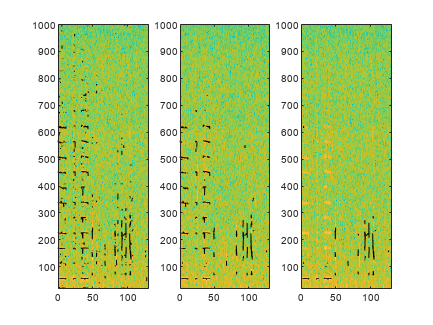

poin = poi(5977);
[f, S, Smed, Sden, St] = Features.Spectrograms(poin);
Cdata = Features.Contours(Sden, St, f);

t = (0:size(S,2)-1)*(POI.Nfft - POI.Noverlap)/POI.fs;

figure
ax1 = subplot(131);
Tools.plotTF(S, f, false, true, t);
hold on
for c = Cdata
    plot(t(c.tmin:c.tmax), c.f0, 'k-')
end
hold off


Cdata = Features.RemoveShortContours(Cdata, POI.Nmin);

ax2 = subplot(132);
Tools.plotTF(S, f, false, true, t);
hold on
for c = Cdata
    plot(t(c.tmin:c.tmax), c.f0, 'k-')
end
hold off


Cdata = Features.RemoveHarmonics(Cdata);

ax3 = subplot(133);
Tools.plotTF(S, f, false, true, t);
hold on
for c = Cdata
    plot(t(c.tmin:c.tmax), c.f0, 'k-')
end
hold off

linkaxes([ax1 ax2 ax3], 'x')

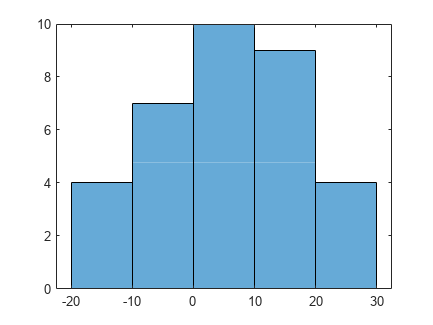


cfeats = Features.Construct(Cdata, poin, St, Sden, S);

D = cell2mat(cfeats);

figure
histogram([D.BLSNR])

figure
Features.plot(cfeats{9});

